# Plotting Beacon data in Global Frame

Objective: This script will show you how to read the Beacon data and transform the data from the sensor frame to the robot frame using *transform_points*. This will then plot the sensed beacon locations in the **global frame**. 

Cheat Sheet: In this script, you will use the following functions and CreateRobot properties:

- RealSenseTag(CreateRobot):  returns the position of beacon in the map along with other information. Note that the position is in x,y coordinates in the sensor reference frame.  (look at this object) * TODO: if help doesnt provide this info, tell them what data structure comes back and how to access the x,y pos*

- genOverhead(CreateRobot): returns the position of the robot from the overhead?. It returns a vector containing the x, y, th positions of the robot. 

- CreateRobot.radius:  returns the radius of the robot

For more information on these functions an properties, refer to the CreateRobot documentation 

help CreateRobot %in Command Window

  Creates definition of class, instances of which will include all
  properties and controls associated with a single CreateRobot robot

    Documentation for CreateRobot



Helper Functions used in this exercise:

- *plot_beacon_transform: *Plots the beacons detected in the global frame

Execise:

In the Simulator, press the Read Sensors button to get the CreateRobot object that represents the current state of the robot. You will use the object (named **robotObj**) in this script.

**Beacon Sensor: **On the Create, the camera of the Beacon sensor is situated directly on the edge of the robot directly in front (along the x-axis of the robot frame) and is oriented in the same direction. This is what defines the origin of the sensor reference frame. 

Complete the code below to:

- Initialize robot constraints based on the CreateRobot and sensor configuration. 

- Obtain the robot pose

- Read Beacon Sensor

- Identify the location of each beacons in the map. Just like the LIDAR sensor you will need to transform the each data point to the global frame. 

**COMPLETE THE CODE BELOW**

%1. Initialize robot constraints based on the CreateRobot and sensor configuration. 
robotRadius = robotObj.radius; %Insert your code here
beacon_pose = [robotRadius; 0; 0];%Insert your code here

%2. Obtain the robot pose
% Read the current position of the robot from the overhead
[x, y, th]= genOverhead(robotObj);%Insert your code here
robot_pose = [x; y; th]; 

%3. Read Beacon Data
tags = RealSenseTag(robotObj,map);%Insert your code here

%4. Identify the location of each beacon in the map
%Create a for-loop to transform each beacon that the sensor reads. 

% Store in dataxy_global which is a 2-by-N matrix, where each column is
% the xy location of the beacon
dataxy_global = zeros(2,size(tags,1)); 

%Insert your code here. 
for i = 1:size(tags,1)
    beacon_number = round(tags(i,2)); % Gets beacon number
    dataxy_sensor = tags(i, 3:4)'; %Read the position from each beacon
    
    % Transform data from sensor frame to robot frame
    dataxy_robot= transform_points(beacon_pose,dataxy_sensor);%Insert your code here
    % Transform data from robot frame to global frame
    dataxy_global(:,i) = transform_points(robot_pose, dataxy_robot); %Insert your code here
end
  

Plot Results

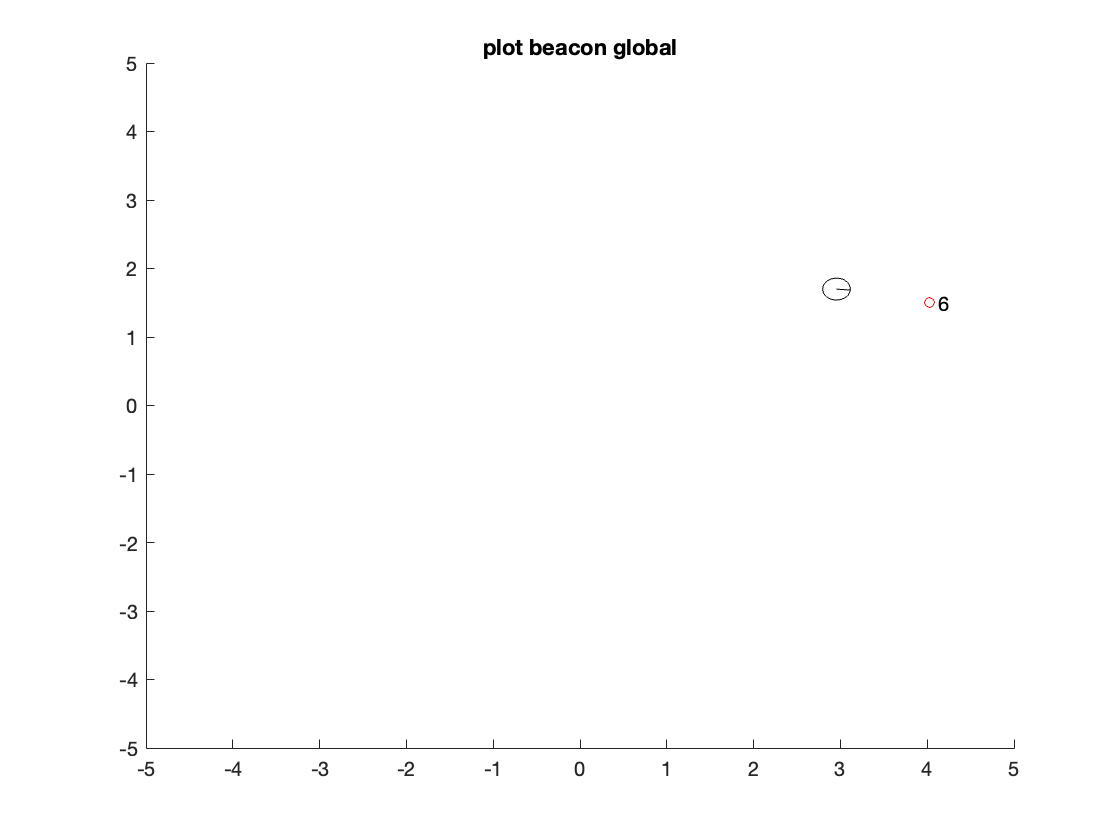

%Plot
plot_beacon_transform(tags, dataxy_global, robot_pose, robotRadius); 

Expected Results: Because you are plotting the beacon data in the **global frame**, you should see the beacon plotted just as you would see the beacons in the map in the simulator.

Check your Comprehension: Is the beacon position plotted as expected? Move the robot around the map facing different beacons and compare the plots. By moving the robot around, can you define the sensor footprint of the beacon sensor?